# Test My DWT for EEG

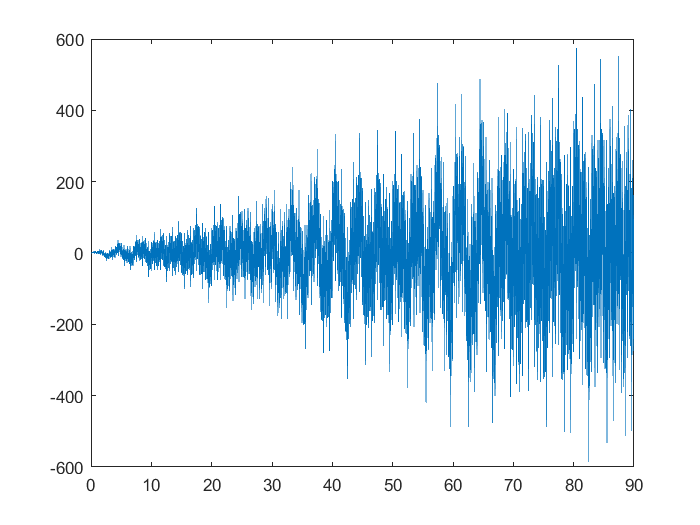

Approx


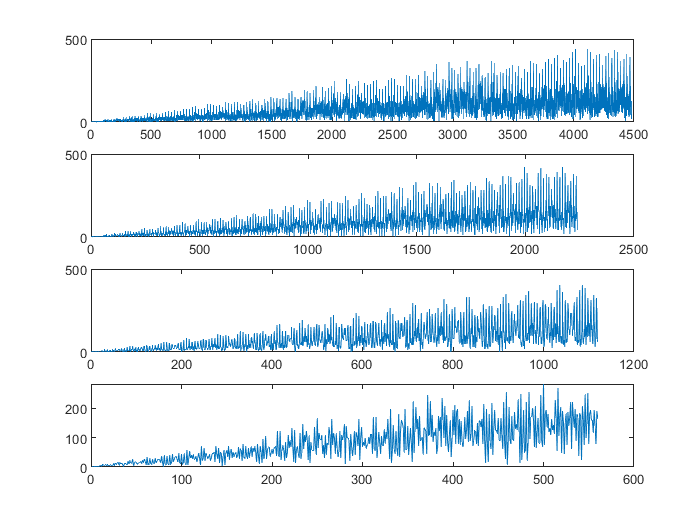

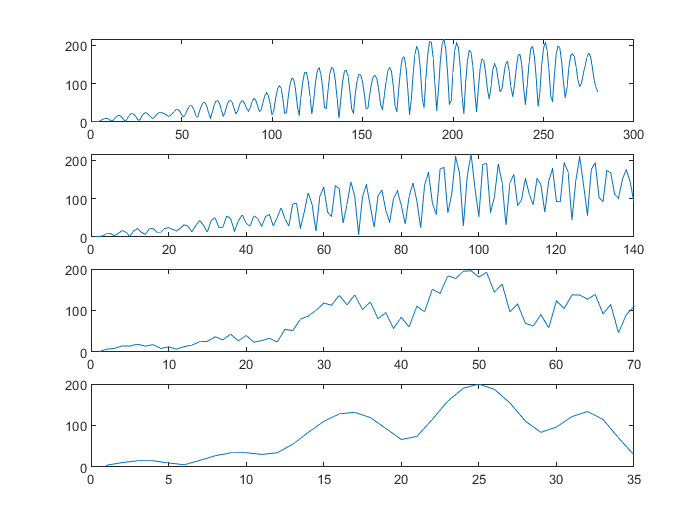

Detail


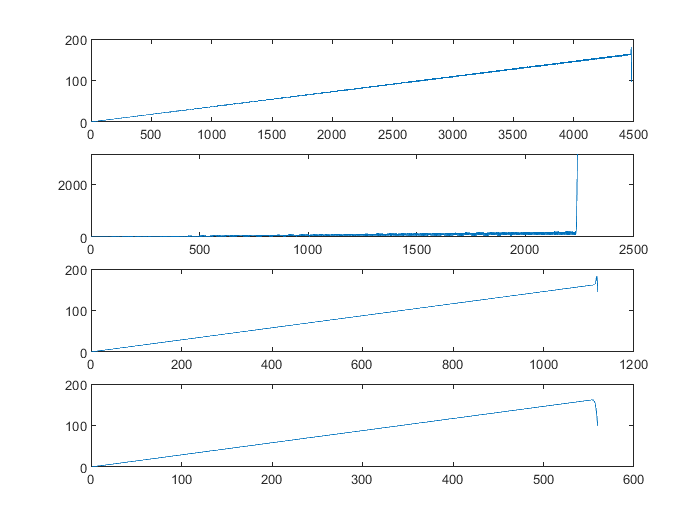

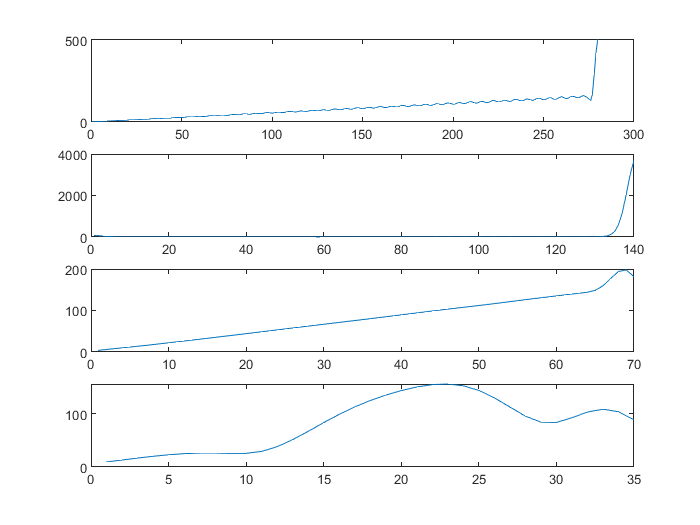

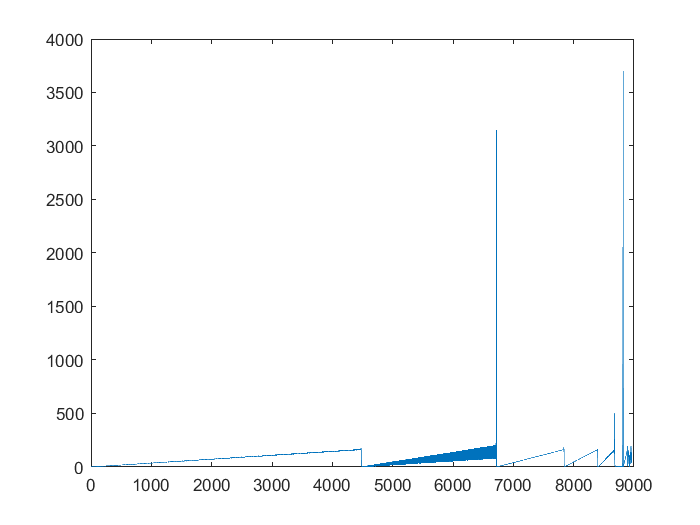

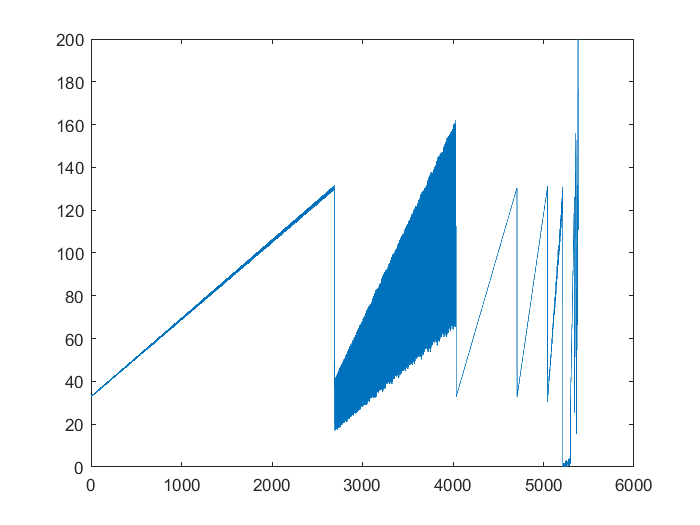

signal_mode = 'test' ;
switch signal_mode
    case 'from_MATLAB'
        load mtlb % mtlb.mat (4001 x 1) ; Fs = 7418 ;
        X = mtlb;
        N = length(X);
        N = N-1;            % X has N+1 points including the start and the end points.
        time = (0:N) ./ Fs ;
        T = N / Fs ;
    case 'test'
        T = 90 ;
        Fs = 100 ;
        N = T * Fs ;
        time = (0:N)' ./ Fs ;
        X = time .* sum(sin(2*pi.*([0.25 0.28 0.3 0.7 3 5 7 9 15 30 45]' * time')),1)';
    case 'EEG_test'                 % EEG data
        load EEG_test.mat           % x : time signal , fs = 100 : sampling rate ;
        N = length(X) - 1 ;
        time = (0:N) ./ Fs ;
        T = N / Fs ;
    case 'STFT_test_signal'         % 3Hz | 11Hz | 8Hz
        load STFT_test_signal.mat   % x : time signal , fs = 500 : sampling rate ;
        X = x ;
        Fs = fs ;
        N = length(X) - 1 ;
        time = (0:N) ./ Fs ;
        T = N / Fs ; 
        downsample(X,4) ;
        Fs = Fs/4 ;
end
% Plot X
plot(time,X) ;

if length(X) < 2^8
    error("The length of signal is too short!") ;
end
temp = floor(length(X) / 2^8) ;
temp = length(X) - 2^8 * temp ;
temp1 = floor(temp/2) ;
temp2 = ceil(temp/2) ;
X = X(1 + temp1 : end - temp2) ;

M = length(X) - 1 ;
[P,S,t0_P,t0_S,omega_0] = Get_my_dwt_wavelet(M,Fs) ;
W = cell(9,2) ;
W{1,2} = X ;
for i = 2:9
    [W{i,1},W{i,2}] = My_DWT_for_EEG(W{i-1,2},P,S,t0_P,t0_S) ;
end

disp("Approx") ;
figure();
for i = 1:4
    subplot(4,1,i) ;
    plot(abs(W{i+1,2})) ;
end
figure();
for i = 1:4
    subplot(4,1,i) ;
    plot(abs(W{i+5,2})) ;
end
disp("Detail") ;
figure();
for i = 1:4
    subplot(4,1,i) ;
    plot(abs(W{i+1,1})) ;
end
figure() ;
for i = 1:4
    subplot(4,1,i) ;
    plot(abs(W{i+5,1})) ;
end

figure();
W1 = [W(2:end,1) ; W(end,2)] ;
W1 = cell2mat(W1) ;
plot(abs(W1)) ;

figure();
W2 = [W(2:end,1) ; W(end,2)] ;
for i = 1:9
    W2{i} = W2{i}(ceil(end/5) : floor(end*4/5)) ;
end
W2 = cell2mat(W2) ;
plot(abs(W2)) ;